# **JacobiND**

[Jacobi elliptic function nd](https://dlmf.nist.gov/22)

## Definition


$$\mathrm{nd}\left(x\left|m\right.\right)\equiv \frac{1}{\mathrm{dn}\left(x\left|m\right.\right)}$$



$$\mathrm{nd}\left(x,k\right)\equiv \mathrm{nd}\left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, and  dn is Jacobi elliptic function.

Domain: $-\infty <x<\infty$, $-\infty <m<\infty$. For the specified domain, the  codomain of nd is the set of real numbers.

Basic features:

$\mathrm{nd}\left(x+2K\left(m\right)\left|m\right.\right)=\mathrm{nd}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{nd}\left(-x\left|m\right.\right)=\mathrm{nd}\left(x\left|m\right.\right)$ (even)

Special values:


$$\mathrm{nd}\left(0\left|m\right.\right)=1$$


$\mathrm{nd}\left(x\left|0\right.\right)=1$,  $\mathrm{nd}\left(x\left|1\right.\right)=\textrm{co}\textrm{sh}\;x$

Identities:


$$\mathrm{nd}\left(x\left|m\right.\right)=\mathrm{nc}\left(x\sqrt{m}\left|m^{-1} \right.\right)$$



$$\textrm{dn}\left(x+K\left(m\right)\left|m\right.\right)=\sqrt{1-m}\;\textrm{nd}\left(x\left|m\right.\right)$$


## Syntax

Y = JacobiND(X,K)

y = jnd(x,k)

Y = mJacobiND(X,M)

y = mjnd(x,m)

## Dendription

Y = JacobiND(X,K) returnd the Jacobi elliptic fundtion $\mathrm{nd}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be ndalar. **JacobiND** is the wrapper fundtion which calls the fundtiond **jnd** element-wise via the fundtion **ufun2**.

y = jnd(x,k) returnd the Jacobi elliptic fundtion $\mathrm{nd}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real ndalars without check. The fundtion returnd NaN if either of  the arguments is invalid or convergende failed. **jnd** calls the fundtiond **sndndn **for calculation of$\;\mathrm{nd}\left(x,k\right)$ .

Y = mJacobiND(X,M) returnd the Jacobi elliptic fundtion $\mathrm{nd}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be ndalar. **mJacobiND** is the wrapper fundtion which calls the fundtion **mjnd** element-wise via the fundtion **ufun2**.

y = mjnd(x,m) returnd the Jacobi elliptic fundtion $\mathrm{nc}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real ndalars without check. The fundtion returnd NaN if either of  the arguments is invalid or convergende failed.  **mjnd** calls the fundtiond **sndndn **for calculation of $\mathrm{nd}\left(x\left|m\right.\right)$ .

**sndndn **implements the AGM trandformation for simultaneously  computation of the fundtiond *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

## **Numerical Examples**

**Salar input**

format long
k = 0.5; 
x = 0.5;
[jnd(x,k), JacobiND(x,k), mjnd(x,k^2), mJacobiND(x,k^2)]

ans =    1.029465994572300   1.029465994572300   1.029465994572300   1.029465994572300


Accuracy

fprintf('%.16g\n',jnd(3,5))

-1.541551093231429


% Maple -1.5415510932314259_6

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobind.html)

format short
disp(mJacobiND([2 1 -3],[1 2 3]))

    3.7622    3.2181 -218.7739



fprintf('%.16g\n',mjnd(3,5))

1.002433849705501


% MATLAB 1.002433849705500_6289470589737758


Identities

x=2;
m = 0.12; % m > 0
disp(mjnd(x,m)-mjnc(x*sqrt(m),1/m))

     0



disp(mjnd(-x,m)-mjnd(x,m))  % even

     0



disp(mjnd(x+2*melK(m),m)-mjnd(x,m))  % periodic

     0



k = 0.2;
x = 12.

x = 12

disp(jdn(x+elK(k),k)-sqrt(1-k^2)*jnd(x,k))

   2.2204e-16



**Vector input**

X=[1 2 3 4];
disp(JacobiND(X,0)-ones(size(X)))

     0     0     0     0



X=[1 2 3 4];
disp(JacobiND(X,1)-cosh(X))

   1.0e-14 *

         0   -0.0444         0    0.3553



m = 0.12; 
disp(mJacobiND(X,m)-mJacobiNC(X*sqrt(m),1/m))

     0     0     0     0



**Matrix input**

X=[1 2; 3 4];
disp(JacobiND(X,1)-cosh(X))

   1.0e-14 *

         0   -0.0444
         0    0.3553



M = [1 2; 0.2 0.3]; 
disp(mJacobiND(X,M)-mJacobiNC(X.*sqrt(M),1./M))

     0     0
     0     0



## **Graphs **

**Example 1**

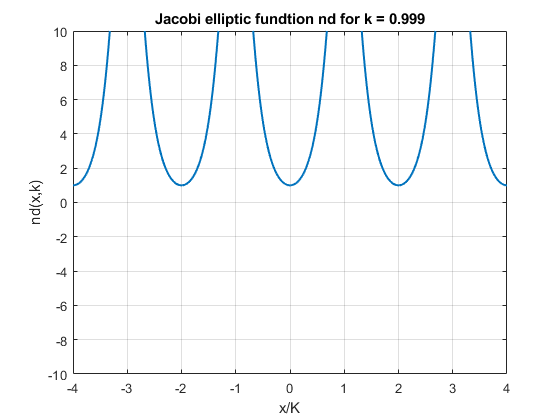

figure
x=-4:0.01:4;
k = 0.999;
K = elK(k);
plot(x,JacobiND(x*K,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('nd(x,k)')
ylim([-10 10])
title(sprintf('Jacobi elliptic fundtion nd for k = %g',k))
grid on

**Example 2**

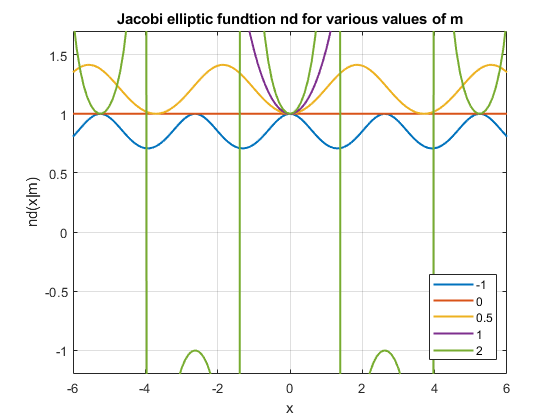

figure
X = -6:0.1:6;
M = [-1,0,0.5,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiND(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi elliptic fundtion nd for various values of m')
xlabel('x')
ylabel('nd(x|m)')

**Example 3**

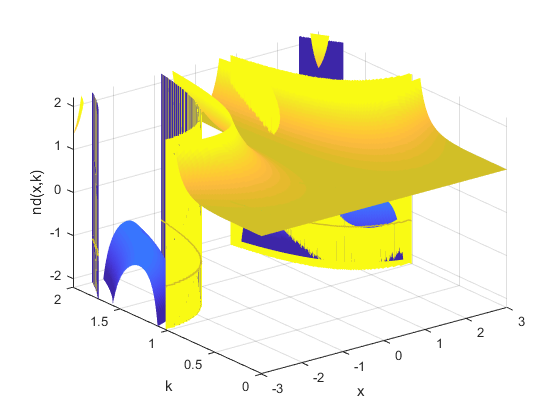

figure
x=-3:0.01:3;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiND(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1.2;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([-2 2])
view(3);
xlabel('x')
ylabel('k')
zlabel('nd(x,k)')
zlim([-2.2 2.2])
grid on

**Example 4**

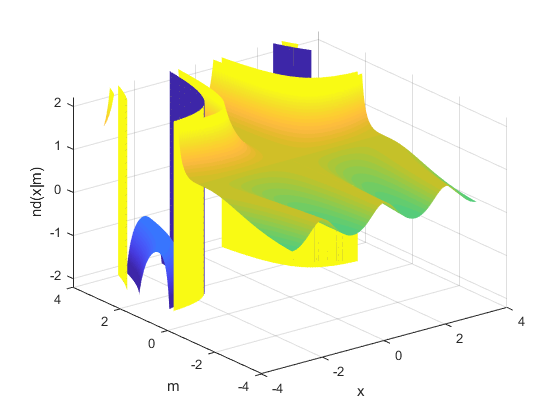

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiND(X,M),'EdgeColor','none')
view(3)
caxis([-2 2])
xlabel('x')
ylabel('m')
zlabel('nd(x|m)')
zlim([-2.2 2.2])
grid on

**Example 5**

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobind.html)

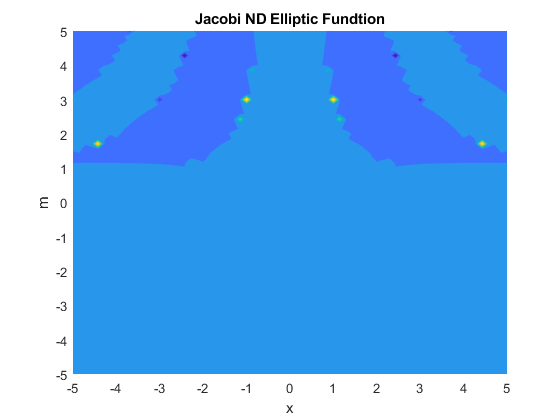

figure
f = @(x,m)mJacobiND(x,m);
fcontour(f,'Fill','on') %,'LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi ND Elliptic Fundtion')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Fundtiond](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Fundtiond, NIST Digital Library of Mathematical Fundtiond](https://dlmf.nist.gov/22)

[Jacobi elliptic fundtiond, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **Referendes**

[1] R. Bulirndh, Numerical Calculation of Elliptic Integrals and Elliptic Fundtiond. Numerindhe Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also